# RRPR Manipulator 

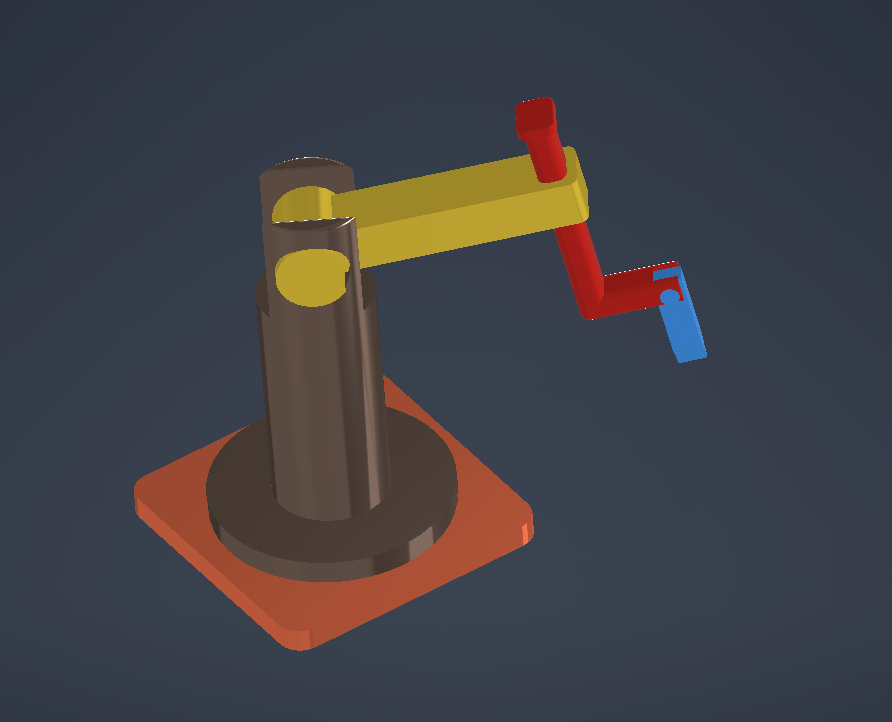

## DH Paramters

%sympref('AbbreviateOutput', true)
syms l_1 l_2 l_32 l_4 theta_1 theta_2 d_3 theta_4;
sympref('AbbreviateOutput',false);

DH=[sym(0),sym(0),l_1,theta_1;...
    -sym(pi/2),sym(0),0,theta_2;...
    -sym(pi/2),l_2,d_3,sym(0);...
    sym(pi/2),l_32,sym(0),theta_4]

$$DH = \left(\begin{array}{cccc} 0 & 0 & l_{1} & \theta_{1}\\ -\frac{\pi }{2} & 0 & 0 & \theta_{2}\\ -\frac{\pi }{2} & l_{2} & d_{3} & 0\\ \frac{\pi }{2} & l_{32} & 0 & \theta_{4} \end{array}\right)$$

## Forward Kinematics

% First Homogeneous Transformation from frame 1 to frame 0
T01 =simplify(HTM(DH(1,1),DH(1,2),DH(1,3),DH(1,4)))

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Second Homogeneous Transformation from frame 2 to frame 1
T12=simplify(HTM(DH(2,1),DH(2,2),DH(2,3),DH(2,4)))

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Third Homogeneous Transformation from frame 3 to frame 2
T23=simplify(HTM(DH(3,1),DH(3,2),DH(3,3),DH(3,4)))

$$T23 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}\\ 0 & 0 & 1 & d_{3}\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Fourth Homogeneous Transformation from frame 4 to frame 3
T34=simplify(HTM(DH(4,1),DH(4,2),DH(4,3),DH(4,4)))

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & l_{32}\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% The Homogeneous Transformation from frame 2 to frame 0
T02=simplify(T01*T12)

$$T02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & 0\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right) & 0\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% The Homogeneous Transformation from frame 3 to frame 0
T03=simplify(T02*T23)

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)\\ -\sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) & l_{1}-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% The Forward Kinematics 
T04=simplify(T03*T34)

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)\\ \cos\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)\\ -\sin\left(\theta_{2}+\theta_{4}\right) & -\cos\left(\theta_{2}+\theta_{4}\right) & 0 & l_{1}-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)-l_{32}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% The Homogeneous Transformation from frame P to frame 0
T0P=simplify(T04*[  1,0,0, 0;...
                    0,1,0,l_4;...
                    0,0,1, 0;...
                    0,0,0, 1])

$$T0P = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}+\theta_{4}\right) & -\cos\left(\theta_{2}+\theta_{4}\right) & 0 & l_{1}-l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)-l_{32}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%v=T04*[0;l_4;0;1]

%test1= subs(T0P,{theta_1, theta_2, d_3, theta_4},{0,sym(-pi/2),0,0})
% this test is for initial position of robot
test2= subs(T0P,{theta_1, theta_2, d_3, theta_4},{0,0,0,0})

$$test2 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}+l_{32}\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & l_{1}-l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Jacobian

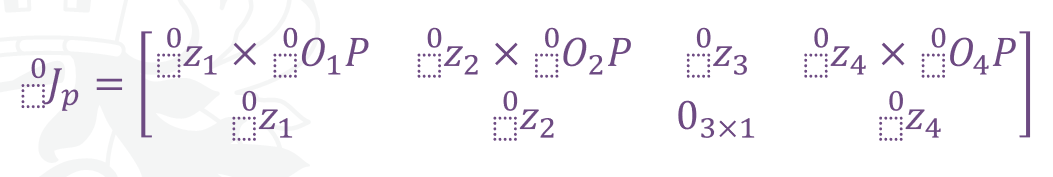

% Rotation Matrices
R01=T01(1:3,1:3)

$$R01 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R02=T02(1:3,1:3)

$$R02 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 \end{array}\right)$$

R03=T03(1:3,1:3)

$$R03 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) \end{array}\right)$$

R04=T04(1:3,1:3)

$$R04 = \left(\begin{array}{ccc} \cos\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}+\theta_{4}\right) & -\cos\left(\theta_{2}+\theta_{4}\right) & 0 \end{array}\right)$$


% Joint axes in the base frame
z1=R01*[0;0;1]

$$z1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

z2=R02*[0;0;1]

$$z2 = \left(\begin{array}{c} -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

z3=R03*[0;0;1]

$$z3 = \left(\begin{array}{c} -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{2}\right) \end{array}\right)$$

z4=R04*[0;0;1]

$$z4 = \left(\begin{array}{c} -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$


O0P=T0P(1:3,4) % in the base frame

$$O0P = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ l_{1}-l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)-l_{32}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

O0O1=T01(1:3,4) % in the base frame

$$O0O1 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

O1P=O0P-O0O1 % in the base frame

$$O1P = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)-l_{32}\,\sin\left(\theta_{2}\right) \end{array}\right)$$


O0O2=T02(1:3,4) % in the base frame

$$O0O2 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

O2P=O0P-O0O2 % in the base frame

$$O2P = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)-l_{32}\,\sin\left(\theta_{2}\right) \end{array}\right)$$


O0O4=T04(1:3,4) % in the base frame

$$O0O4 = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)\\ \sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)\\ l_{1}-d_{3}\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{2}\right)-l_{32}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

O4P=O0P-O0O4 % in the base frame

$$O4P = \left(\begin{array}{c} -l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ -l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right) \end{array}\right)$$


Jv = [cross(z1,O1P),cross(z2,O2P),z3,cross(z4,O4P)]

$$Jv = \left(\begin{array}{cccc} l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right) & -\cos\left(\theta_{1}\right)\,\left(l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)+d_{3}\,\cos\left(\theta_{2}\right)+l_{2}\,\sin\left(\theta_{2}\right)+l_{32}\,\sin\left(\theta_{2}\right)\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\left(l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)+d_{3}\,\cos\left(\theta_{2}\right)+l_{2}\,\sin\left(\theta_{2}\right)+l_{32}\,\sin\left(\theta_{2}\right)\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right)\,\left(\cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\right)-\sin\left(\theta_{1}\right)\,\left(\sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\right) & -\cos\left(\theta_{2}\right) & l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,{\cos\left(\theta_{1}\right)}^{2}+l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,{\sin\left(\theta_{1}\right)}^{2} \end{array}\right)$$

simplify(Jv)

$$ans = \left(\begin{array}{cccc} l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right) & -\cos\left(\theta_{1}\right)\,\left(l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)+d_{3}\,\cos\left(\theta_{2}\right)+l_{2}\,\sin\left(\theta_{2}\right)+l_{32}\,\sin\left(\theta_{2}\right)\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\left(l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)+d_{3}\,\cos\left(\theta_{2}\right)+l_{2}\,\sin\left(\theta_{2}\right)+l_{32}\,\sin\left(\theta_{2}\right)\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ 0 & l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)-l_{2}\,\cos\left(\theta_{2}\right)-l_{32}\,\cos\left(\theta_{2}\right)+d_{3}\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right) \end{array}\right)$$


Jw = [z1,z2,zeros(3,1),z4]

$$Jw = \left(\begin{array}{cccc} 0 & -\sin\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right)\\ 0 & \cos\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)$$


J=[Jv;Jw]

rank = rank(J)

rank = 4

simplify(J)

$$ans = \left(\begin{array}{cccc} l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right) & -\cos\left(\theta_{1}\right)\,\left(l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)+d_{3}\,\cos\left(\theta_{2}\right)+l_{2}\,\sin\left(\theta_{2}\right)+l_{32}\,\sin\left(\theta_{2}\right)\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\left(l_{2}\,\cos\left(\theta_{2}\right)+l_{32}\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{2}\right)\right)-l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\left(l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)+d_{3}\,\cos\left(\theta_{2}\right)+l_{2}\,\sin\left(\theta_{2}\right)+l_{32}\,\sin\left(\theta_{2}\right)\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{4}\,\cos\left(\theta_{2}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ 0 & l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)-l_{2}\,\cos\left(\theta_{2}\right)-l_{32}\,\cos\left(\theta_{2}\right)+d_{3}\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & l_{4}\,\sin\left(\theta_{2}+\theta_{4}\right)\\ 0 & -\sin\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right)\\ 0 & \cos\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)$$

### 2D case

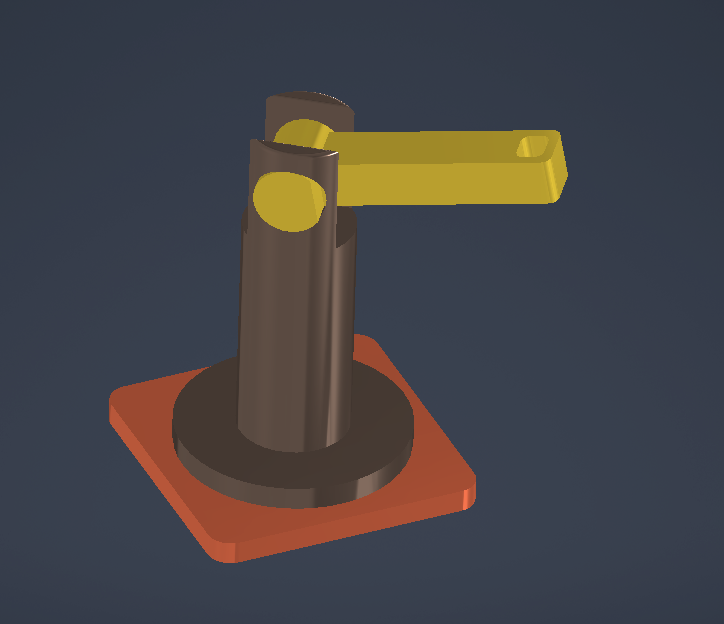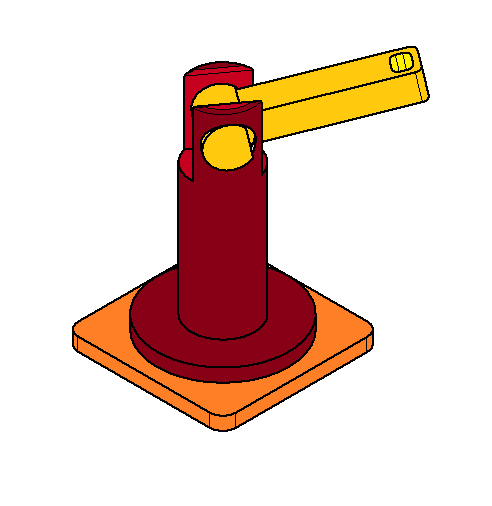

now it became RR

% Clear all variablesv=
clear

syms l_g1 l_g2 theta_1 theta_2 d_3 l1 l2
DH= [sym(0),sym(0),l1,theta_1;...
     sym(-pi/2), sym(0),0 , theta_2]

$$DH = \left(\begin{array}{cccc} 0 & 0 & l_{1} & \theta_{1}\\ -\frac{\pi }{2} & 0 & 0 & \theta_{2} \end{array}\right)$$


% First Homogeneous Transformation from frame 1 to frame 0
T01 =simplify(HTM(DH(1,1), DH(1,2), DH(1,3), DH(1,4)))

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Second Homogeneous Transformation from frame 2 to frame 1
T12=simplify(HTM(DH(2,1), DH(2,2), DH(2,3), DH(2,4)))

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Homogeneous Transformation from frame 2 to frame 0
T02=T01*T12

$$T02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & 0\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right) & 0\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Interediate Jacobian 

The Jacobians at the COM of links are:


$$J_{G_1 } =\left\lbrack \begin{array}{cc}
\vec{z_1 } \times \vec{O_1 G_1 }  & 0_{3\times 1} \\
\vec{z_1 }  & 0_{3\times 1} 
\end{array}\right\rbrack$$
                                                          
$$J_{G_2 } =\left\lbrack \begin{array}{cc}
\vec{z_1 } \times \vec{O_1 G_2 }  & \vec{z_2 } \times \vec{O_2 G_2 } \\
\vec{z_1 }  & \vec{z_2 } 
\end{array}\right\rbrack$$


all vectors are expressed in the base frame

v=T01*[0;0;-l_g1;1]; % o0g1 
O0G1=v(1:3,1)

$$O0G1 = \left(\begin{array}{c} 0\\ 0\\ l_{1}-l_{\mathrm{g1}} \end{array}\right)$$

O0O1=T01(1:3,4) % o0g1 

$$O0O1 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

O1G1=O0G1-O0O1

$$O1G1 = \left(\begin{array}{c} 0\\ 0\\ -l_{\mathrm{g1}} \end{array}\right)$$

% R01*[0;0;-l_g1]

% Jv_1 = [cross(z1, O1G1), [sym(0); sym(0); sym(0)]]
% Jw_1 = [z1, [sym(0); sym(0); sym(0)]]
% J1 = [Jv_1 ; Jw_1]
R01=T01(1:3,1:3);
z1=R01*[0;0;1]

$$z1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

J1=[cross(z1,O1G1),zeros(3,1);z1,zeros(3,1)]

$$J1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$


R02=T02(1:3,1:3);
z2=R02*[0;0;1];
v=T02*[l2-l_g2;0;0;1];
O0O2=T02(1:3,4) % o0o2

$$O0O2 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

O0G2=v(1:3,1)

$$O0G2 = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ l_{1}-\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) \end{array}\right)$$

O2G2=O0G2-O0O2

$$O2G2 = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ -\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) \end{array}\right)$$

O1G2 =O0O1-O0G2 

$$O1G2 = \left(\begin{array}{c} -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ \sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) \end{array}\right)$$


% Jv_2 = [cross(z1, O1G2), cross(z2, O2G2)]
% Jw_2 = [z1, z2]
% J2 = [Jv_2 ; Jw_2]
J2=[cross(z1,O1G2),cross(z2,O2G2);z1,z2]

$$J2 = \left(\begin{array}{cc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\cos\left(\theta_{1}\right)}^{2}-\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\sin\left(\theta_{1}\right)}^{2}\\ 0 & -\sin\left(\theta_{1}\right)\\ 0 & \cos\left(\theta_{1}\right)\\ 1 & 0 \end{array}\right)$$

### Mass Matrix

Jv_1=J1(1:3,:)

$$Jv\_1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

Jw_1=J1(4:6,:)

$$Jw\_1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

Jv_2=J2(1:3,:)

$$Jv\_2 = \left(\begin{array}{cc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\cos\left(\theta_{1}\right)}^{2}-\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\sin\left(\theta_{1}\right)}^{2} \end{array}\right)$$

Jw_2=J2(4:6,:)

$$Jw\_2 = \left(\begin{array}{cc} 0 & -\sin\left(\theta_{1}\right)\\ 0 & \cos\left(\theta_{1}\right)\\ 1 & 0 \end{array}\right)$$


syms I_1_1 I_1_2 I_1_3 I_2_1 I_2_2 I_2_3 m_1 m_2

%I_1_1 = 12322988.766;
%I_1_2 = 12397645.505;
%I_1_3 = 3824563.209;

%I_2_1 = 286596.934;
%I_2_2 = 2518314.109;
%I_2_3 = 2637109.912;

I1 = [I_1_1, sym(0), sym(0); sym(0), I_1_2, sym(0); sym(0), sym(0),I_1_3]

$$I1 = \left(\begin{array}{ccc} I_{1,1} & 0 & 0\\ 0 & I_{1,2} & 0\\ 0 & 0 & I_{1,3} \end{array}\right)$$

I2 = [I_2_1, sym(0), sym(0); sym(0), I_2_2, sym(0); sym(0), sym(0),I_2_3]

$$I2 = \left(\begin{array}{ccc} I_{2,1} & 0 & 0\\ 0 & I_{2,2} & 0\\ 0 & 0 & I_{2,3} \end{array}\right)$$

M = m_1 * transpose(Jv_1) * Jv_1 + transpose(Jw_1) * R01 * I1 *transpose(R01) * Jw_1 + m_2 * transpose(Jv_2) * Jv_2 + transpose(Jw_2)* R02 * I2 * transpose(R02) * Jw_2

$$M = \left(\begin{array}{cc} I_{1,3}+I_{2,2}\,{\cos\left(\theta_{2}\right)}^{2}+I_{2,1}\,{\sin\left(\theta_{2}\right)}^{2}+m_{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2}+m_{2}\,{\cos\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{1}\right)}^{2}\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2} & \sin\left(\theta_{1}\right)\,\left(I_{2,1}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)-I_{2,2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\right)-\cos\left(\theta_{1}\right)\,\left(I_{2,1}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-I_{2,2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ 0 & m_{2}\,{\left(\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\cos\left(\theta_{1}\right)}^{2}+\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\sin\left(\theta_{1}\right)}^{2}\right)}^{2}+I_{2,3}\,{\cos\left(\theta_{1}\right)}^{2}\,\left({\cos\left(\theta_{1}\right)}^{2}+{\sin\left(\theta_{1}\right)}^{2}\right)+I_{2,3}\,{\sin\left(\theta_{1}\right)}^{2}\,\left({\cos\left(\theta_{1}\right)}^{2}+{\sin\left(\theta_{1}\right)}^{2}\right)+m_{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2}+m_{2}\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2} \end{array}\right)$$

simplify(M)

$$ans = \left(\begin{array}{cc} I_{1,3}+I_{2,2}\,{\cos\left(\theta_{2}\right)}^{2}+I_{2,1}\,{\sin\left(\theta_{2}\right)}^{2}+m_{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2}+m_{2}\,{\cos\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{1}\right)}^{2}\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2} & 0\\ 0 & m_{2}\,{l_{2}}^{2}-2\,m_{2}\,l_{2}\,l_{\mathrm{g2}}+m_{2}\,{l_{\mathrm{g2}}}^{2}+I_{2,3} \end{array}\right)$$

### Potential Energy

% Potential Energy of the 1st link
V1 = -(m_1 * [sym(0), sym(0) , -vpa('9.81')] * O0G1)

$$V1 = 9.81\,m_{1}\,\left(l_{1}-l_{\mathrm{g1}}\right)$$

% Potential Energy of the 2nd link 
V2 = -(m_2 * [sym(0), sym(0) , -vpa('9.81')] * O0G2)

$$V2 = 9.81\,m_{2}\,\left(l_{1}-\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\right)$$

% Total Potential Energy
V = V1 + V2

$$V = 9.81\,m_{1}\,\left(l_{1}-l_{\mathrm{g1}}\right)+9.81\,m_{2}\,\left(l_{1}-\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\right)$$

### Centrifugal and Coriolis Vector 

CC1 = [1/2 * diff(M(1, 1), theta_1), diff(M(1, 2), theta_2) - 1/2 *diff(M(2, 2), theta_1); diff(M(1, 2), theta_1) - 1/2 * diff(M(1, 1),theta_2), 1/2 * diff(M(2, 2), theta_2)]

$$CC1 = \left(\begin{array}{cc} 0 & \sin\left(\theta_{1}\right)\,\left(I_{2,1}\,\cos\left(\theta_{1}\right)\,{\cos\left(\theta_{2}\right)}^{2}-I_{2,2}\,\cos\left(\theta_{1}\right)\,{\cos\left(\theta_{2}\right)}^{2}-I_{2,1}\,\cos\left(\theta_{1}\right)\,{\sin\left(\theta_{2}\right)}^{2}+I_{2,2}\,\cos\left(\theta_{1}\right)\,{\sin\left(\theta_{2}\right)}^{2}\right)-\cos\left(\theta_{1}\right)\,\left(I_{2,1}\,{\cos\left(\theta_{2}\right)}^{2}\,\sin\left(\theta_{1}\right)-I_{2,2}\,{\cos\left(\theta_{2}\right)}^{2}\,\sin\left(\theta_{1}\right)-I_{2,1}\,\sin\left(\theta_{1}\right)\,{\sin\left(\theta_{2}\right)}^{2}+I_{2,2}\,\sin\left(\theta_{1}\right)\,{\sin\left(\theta_{2}\right)}^{2}\right)\\ I_{2,2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)-I_{2,1}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)+m_{2}\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2}+m_{2}\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2} & m_{2}\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2}-m_{2}\,\left(\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\cos\left(\theta_{1}\right)}^{2}+\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\sin\left(\theta_{1}\right)}^{2}\right)\,\left(\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\cos\left(\theta_{1}\right)}^{2}+\sin\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right)\,{\sin\left(\theta_{1}\right)}^{2}\right)+m_{2}\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2} \end{array}\right)$$

simplify(CC1)

$$ans = \left(\begin{array}{cc} 0 & 0\\ \frac{\sin\left(2\,\theta_{2}\right)\,\left(m_{2}\,{l_{2}}^{2}-2\,m_{2}\,l_{2}\,l_{\mathrm{g2}}+m_{2}\,{l_{\mathrm{g2}}}^{2}-I_{2,1}+I_{2,2}\right)}{2} & 0 \end{array}\right)$$

CC2 = [diff(M(1, 1), theta_2) + 1/2 * diff(M(1, 2), theta_1),sym(0); sym(0), 1/2 * diff(M(2, 2), theta_1)]

$$CC2 = \left(\begin{array}{cc} 2\,I_{2,1}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)-2\,I_{2,2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)-2\,m_{2}\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2}-2\,m_{2}\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,{\left(l_{2}-l_{\mathrm{g2}}\right)}^{2} & 0\\ 0 & 0 \end{array}\right)$$

simplify(CC2)

$$ans = \left(\begin{array}{cc} -\sin\left(2\,\theta_{2}\right)\,\left(m_{2}\,{l_{2}}^{2}-2\,m_{2}\,l_{2}\,l_{\mathrm{g2}}+m_{2}\,{l_{\mathrm{g2}}}^{2}-I_{2,1}+I_{2,2}\right) & 0\\ 0 & 0 \end{array}\right)$$

### Gravity vector

Gravity = simplify([diff(V, theta_1); diff(V, theta_2)])

$$Gravity = \left(\begin{array}{c} 0\\ -9.81\,m_{2}\,\cos\left(\theta_{2}\right)\,\left(l_{2}-l_{\mathrm{g2}}\right) \end{array}\right)$$

**Equations of motion**

syms theta_dot_1 theta_ddot_1 theta_dot_2

a = [theta_dot_1,theta_ddot_1]

$$a = \left(\begin{array}{cc} {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} \end{array}\right)$$

tau = M*[theta_1;theta_2] + CC1*[theta_dot_1^2;theta_dot_2^2] + CC2*(theta_dot_1*theta_dot_2) + Gravity

simplify(tau)